**Download Dataset**

This data has been pre-processed from [Steinmetz et al. (2019)](https://www.nature.com/articles/s41586-019-1787-x), and is hosted on Sciebo here: [https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J](https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J).

# Analyzing Behavioral Task Performance: Psychometric Analysis on Ordered Categorical Data

In the experiment reported on by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), mice were tasked with turning a wheel to the left or right based on the relative contrast levels of two simultaneously-presented gradient  stimuli:

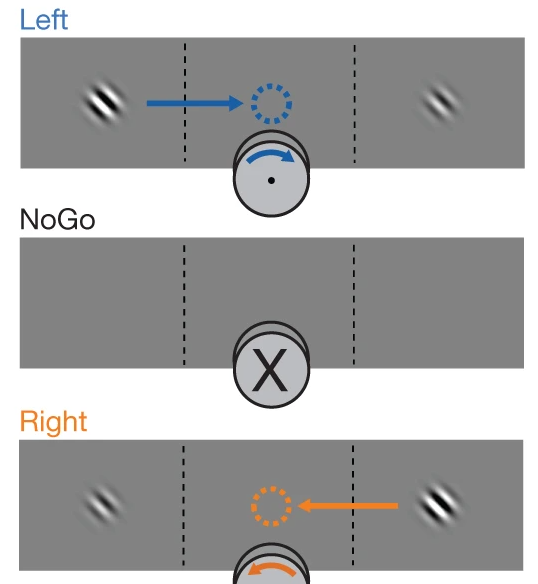

When the left stimuli is brightest, in order to earn a reward, the mouse must turn the wheel to the right. Accordingly when the right stimili is brightest, the mouse must turn the wheel to the right. When both stimili have equal contrasts (including the case where no stimili are shown), the correct response is not to turn the wheel. 

**Analysis Goals**

In this notebook, we'll examine the `response_time` and `response_type` of each trial across all sessions, to determine whether the mice  successfully performed the task, and whether the difference in contrast  levels between the two stimuli affected their performance.

## **Performance Analysis:  Average Response Type for Each Stimulus Contrast Level**

The `response_type` data encodes which way the mouse turned the wheel : -1 corresponds to a left turn, 1 to a right turn and 0 means that the wheel was not turned at all. 

In this section we will analyse the response types across different combinations of left and right contrasts to assess how well the mice performed the task. 

Read in data from .csv file. 

data = readtable("data/all.csv");
data

data = 14420×14 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

      1        {'true'}            100                0            

**Example Exercise**

Make a bar plot showing the mean response type according to contrast right levels

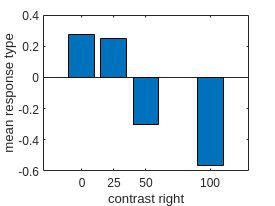

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

bar(mean_response_type.contrast_right, mean_response_type.mean_response_type)

xlabel("contrast right")
ylabel("mean response type")

Bar plot with coloured bars

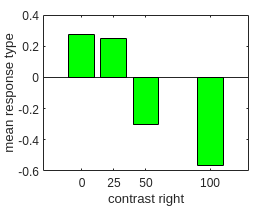

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

bar(mean_response_type.contrast_right, mean_response_type.mean_response_type, "green")

xlabel("contrast right")
ylabel("mean response type")

Horizontal bar plot

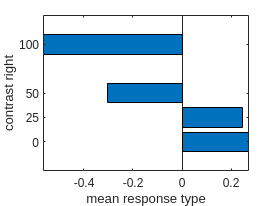

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

barh(mean_response_type.contrast_right, mean_response_type.mean_response_type)

ylabel("contrast right")
xlabel("mean response type")

Bar plot with multiple values 

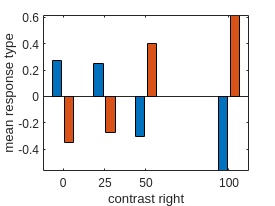

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");
mean_response_type_l = groupsummary(data, "contrast_left", "mean", "response_type");


bar(mean_response_type.contrast_right, horzcat(mean_response_type.mean_response_type, mean_response_type_l.mean_response_type))
%bar(mean_response_type_l.contrast_left, mean_response_type_l.mean_response_type)

xlabel("contrast right")
ylabel("mean response type")

Make bar plot showing mean response type for every combination of contrast left and right .

Needs a lot of explaining!!

aa= groupsummary(data, ["contrast_left","contrast_right"], "mean", "response_type")

aa = 16×4 table
    contrast_left    contrast_right    GroupCount    mean_response_type
    _____________    ______________    __________    __________________

           0                0             2649           -0.072103     
           0               25              738            -0.62931     
           0               50             1078            -0.76308     
           0              100             2735            -0.72275     
          25                0              353             0.56347     
          25               25              255           -0.062222     
          25               50              372            -0.43567     
          25              100              700            -0.66418     
          50                0              767             0.78426     
          50               25              348         

bb=table2array(aa)

bb = 1.0e+03 *

         0         0    2.6490   -0.0001
         0    0.0250    0.7380   -0.0006
         0    0.0500    1.0780   -0.0008
         0    0.1000    2.7350   -0.0007
    0.0250         0    0.3530    0.0006
    0.0250    0.0250    0.2550   -0.0001
    0.0250    0.0500    0.3720   -0.0004
    0.0250    0.1000    0.7000   -0.0007
    0.0500         0    0.7670    0.0008
    0.0500    0.0250    0.3480    0.0005


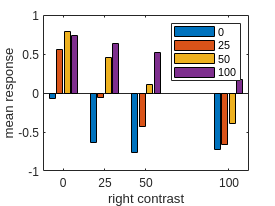

bar([0,25,50,100], reshape( bb(: ,4), [4,4 ]))

legend(["0","25","50","100"], "Location", "northeast");
xlabel('right contrast')
ylabel('mean response')

## Analyzing Response Time and Response Type: Transforming and Filtering Data, and Comparing Estimates

Making new columns in MATLAB tables

In the exercises below, let's practice making new columns in our table. We will then use the newly created column in the next  set of analyses.

**Example Exercise**

Make a new column called `"contrast_total"` that is the sum of the two stimuli's contrast levels.

data.contrast_total = data.contrast_left + data.contrast_right;

The mice had to make a decision of whether to move the wheel left or right based on the *difference* in contrast between the left and right stimulus, not on the actual levels of the data. 

 Make a new column called `contrast_diff` that contains the contrast difference between the left and right stimuli.

data.contrast_diff = data.contrast_left - data.contrast_right;

The mice were not allowed to respond immediately after the stimuli  appeared; instead, they had to wait for the "go cue" to appear, which  was at a randomized time point after the stimuli.  

Let's calculate the a new `response_time_corrected` column, which subtracts the `gocue_time` from the `response_time`.

data.response_time_corrected = data.response_time - data.gocue_time;

Instead of calculating the `contrast_diff`, let's calculate the `contrast_diff_absolute`, where the absolute value of the contrast difference is used, so it is  always positive.  This more-closely shows the decision that the mice had to make, and allows us to use twice as many values for each point  estimation.

data.contrast_diff_absolute = abs(data.contrast_diff);

## **Plotting Response Times and Response Types: Comparing Different Average Estimates **

Let's see how the estimator used changes the information conveyed in a plot.  For each of the two measurements:  response type and response  time, which estimators do you think are the most valuable for this  experiment?

**Example Exercise**

Calculate the mean response type as a function of the contrast difference and plot the result.

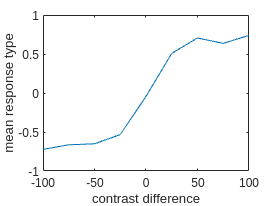

mean_response_type = groupsummary(data, "contrast_diff", "mean", "response_type");
plot(mean_response_type.contrast_diff, mean_response_type.mean_response_type)
xlabel('contrast difference')
ylabel('mean response type')

Calculate the median response type as a function of the contrast difference and plot the result.

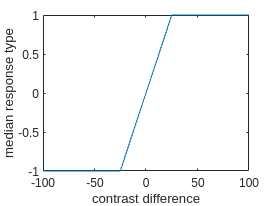

median_response_type = groupsummary(data, "contrast_diff", "median", "response_type");
plot(median_response_type.contrast_diff, median_response_type.median_response_type)
xlabel('contrast difference')
ylabel('median response type')

Calculate the standard deviation of response type as a function of the contrast difference and plot the result.

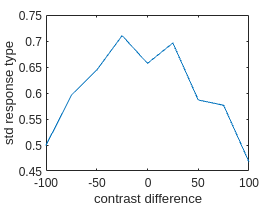

std_response_type = groupsummary(data, "contrast_diff", "std", "response_type");
plot(std_response_type.contrast_diff, std_response_type.std_response_type)
xlabel('contrast difference')
ylabel('std response type')

Calculate the mean response time as a function of the absolute contrast difference and plot the result.

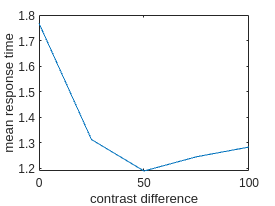

mean_response_time = groupsummary(data, "contrast_diff_absolute", "mean", "response_time");
plot(mean_response_time.contrast_diff_absolute, mean_response_time.mean_response_time)
xlabel('contrast difference')
ylabel('mean response time')

### **Demonstration: Exporting a Figure**

Below is an example showing how multiple lines can be plotted on the same figure. 

Let's plot the mean, median and standard deviation of response type, grouped by contrast difference and save it to a .pdf file.

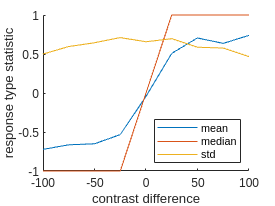

% generate statistics
response_type_stats = groupsummary(data, "contrast_diff", ["mean","median","std"], "response_type");
clf % clear the figure
hold on % freeze the figure for multiple lines
plot(response_type_stats.contrast_diff, response_type_stats.mean_response_type, "DisplayName","mean")
plot(response_type_stats.contrast_diff, response_type_stats.median_response_type, "DisplayName","median")
plot(response_type_stats.contrast_diff, response_type_stats.std_response_type, "DisplayName","std")
hold off % unfreeze

legend ("Location", "southeast") % show legend and set position
xlabel('contrast difference')
ylabel('response type statistic')

% set figure size
fig_width = 12;
fig_height = 8;
set(gcf, 'PaperPosition', [0 0 fig_width fig_height]); %Position plot at left hand corner with width 5 and height 5. 
set(gcf, 'PaperSize', [fig_width fig_height]);

%save figure
saveas(gcf, 'my_figure.pdf')